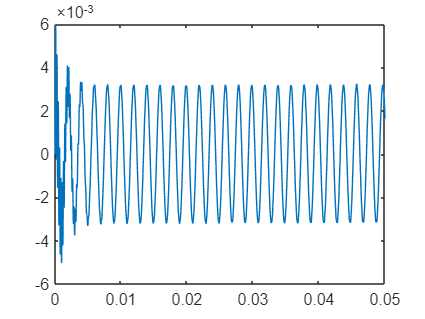

%Ex2

%{
function dx=RLC3_1(t,x)
    R=1e3;
    C=1e-6;
    L=1e-3;
    w=(L*C)^(-0.5);
    u=sin(t*w/10);
    dx=[-1/R/C*x(1)-1/C*x(2)+1/R/C*u;1/L*x(1)];
end
%}
clear variables
%u=sin(0.1wt)
[t,x] = ode23('RLC3_1', [0, 0.05], [0 0]);
plot(t, x(:,1));

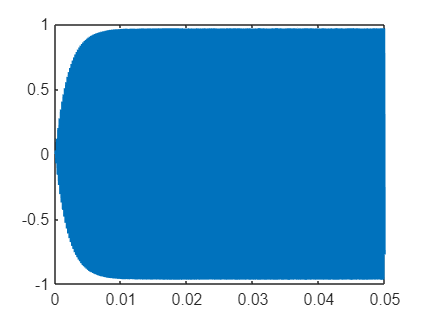


%{
function dx=RLC3_2(t,x)
    R=1e3;
    C=1e-6;
    L=1e-3;
    w=(L*C)^(-0.5);
    u=sin(t*w);
    dx=[-1/R/C*x(1)-1/C*x(2)+1/R/C*u;1/L*x(1)];
end
%}
clear variables
%u=sin(wt)
[t,x] = ode23('RLC3_2', [0, 0.05], [0 0]);
plot(t, x(:,1));

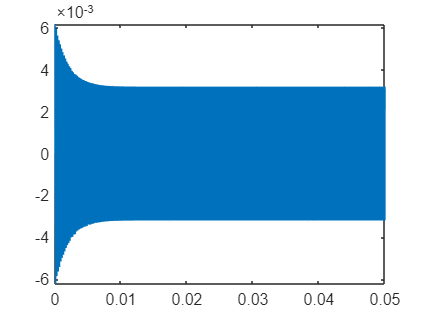


%{
function dx=RLC3_3(t,x)
    R=1e3;
    C=1e-6;
    L=1e-3;
    w=(L*C)^(-0.5);
    u=sin(10*t*w);
    dx=[-1/R/C*x(1)-1/C*x(2)+1/R/C*u;1/L*x(1)];
end
%}
clear variables
%u=sin(10wt)
[t,x] = ode23('RLC3_3', [0, 0.05], [0 0]);
plot(t, x(:,1));


%Ex3
%parametrii circuitului si semnalul de intrare 
%pot fi setati din afara fisierului 'function', 
%in fisierul 'main', declarandu-l global 
%atat in fisierul 'main' cat si in cel 'function'. 
%acest lucru se face folosind urmatoarea sintaxa pt variabila A: 
%"global A;". Astfel variabila A poate fi setata in
%'main' si transmisa in 'function'